+

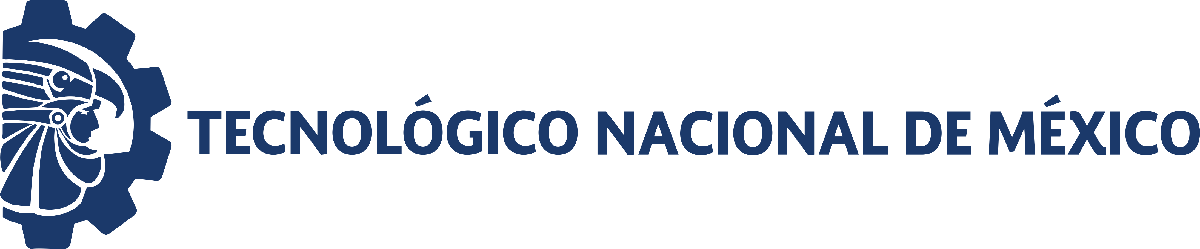                                 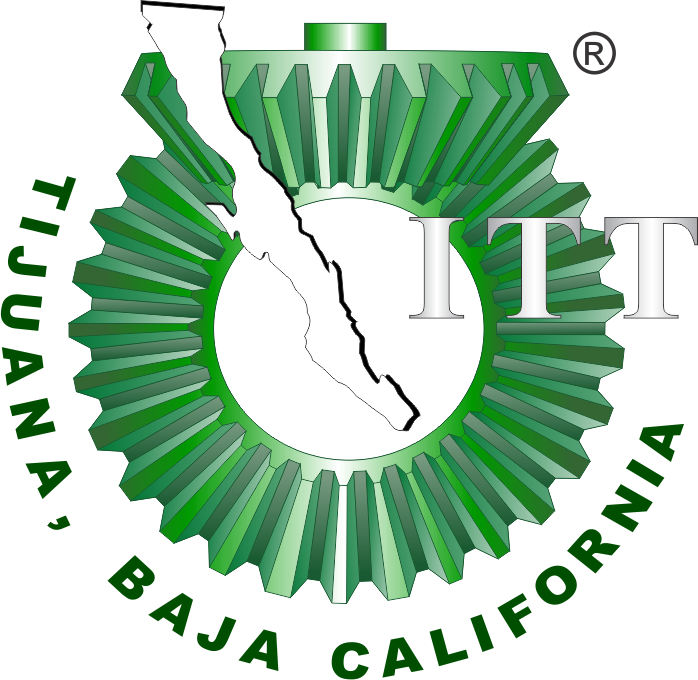

# Practice 6: Final Project.

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

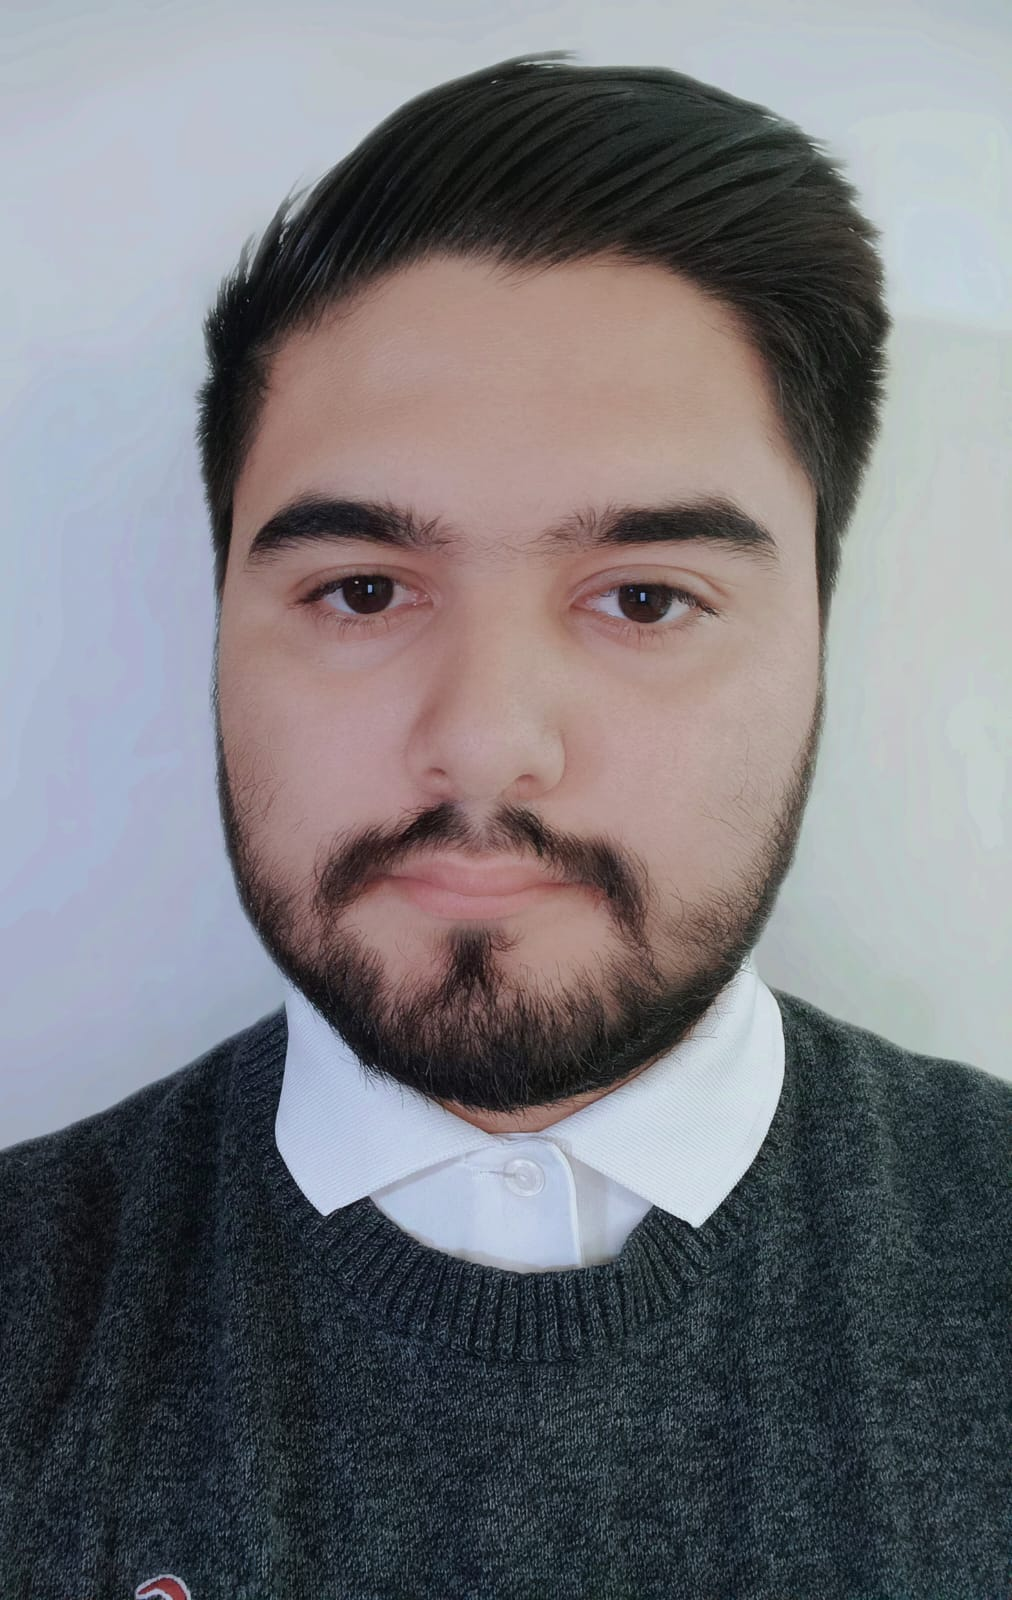

Nombre del alumno: **Jose Sebastian Delgado Soto**

Número de control: **C20212281**

Correo institucional: **l20212281@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## **Objetive**

In this study, we present a dynamical systems model designed to describe the progression of **metastatic melanoma**, an aggressive form of skin cancer characterized by rapid proliferation, tissue invasion, and immune system evasion. The model is formulated using a **three-population system**, represented by three first-order ordinary differential equations, which describe the temporal evolution of key biological populations within the tumor microenvironment.

Specifically, the model considers the interactions between:

### 
$$\dot{\dot{x} =p_1 \textrm{xyz}+p_2 xy^2 }$$


### 
$$\dot{y} =p_3 y-p_4 \textrm{xy}$$


### 
$$\dot{z} =p_5 z-p_6 \textrm{xz}$$


### Populations

- `x(t)` — the population of **melanoma tumor cells**

- `y(t)` — the population of **healthy skin tissue cells**

- `z(t)` — the population of **effector immune cells**, such as **CD8⁺ cytotoxic T lymphocytes** and **natural killer (NK) cells**

### Interpretation

$p_1 \textrm{xyz}=\;$tumor cell growth enhanced by the simultaneous presence of healthy tissue and immune cells (reflecting inflammatory microenvironment and immune evasion mechanisms).

$p_2 xy^2 =\;$aggressive tumor proliferation fueled by the availability of abundant healthy tissue (early-stage expansion).

$p_3 y=\;$ physiological regeneration of healthy skin tissue.

$-p_4 \textrm{xy}$= destruction of healthy tissue due to tumor invasion and local damage.

$p_5 z=\;$ activation and proliferation of effector immune cells in response to tumor presence.

$-p_6 \textrm{xz}=\;$tumor-induced immune suppression (e.g., via PD-L1 expression, TGF-β secretion).

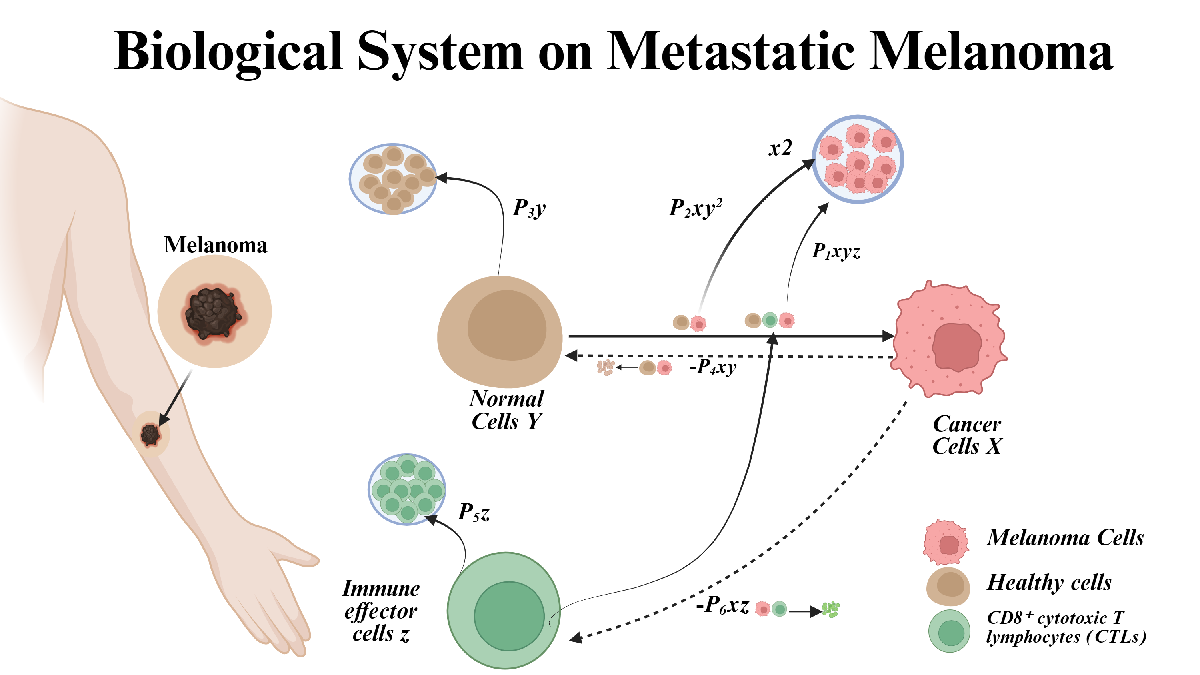

**Figure.** Diagram of the biological three-population system, where *x(t)* represents pathogenic (tumor) cells, *y(t)* represents healthy tissue cells, and *z(t)* represents effector immune cells.

## Simulation data

    Time    x1(t)    y1(t)     z1(t)
    ____    _____    ______    _____

      0     0.517    19.939    0.281
      7      0.58    19.578    0.609
     14     0.726    18.678    1.063
     21     0.965    16.215    1.758
     28     1.282    14.005    2.752
     35     1.825    11.467    3.975
     42     2.473     8.096    4.895
     49     2.974     4.327    6.096
     56      3.43     1.287    7.152
     63     3.717     0.194    7.328
     70     3.829     0.056    7.232



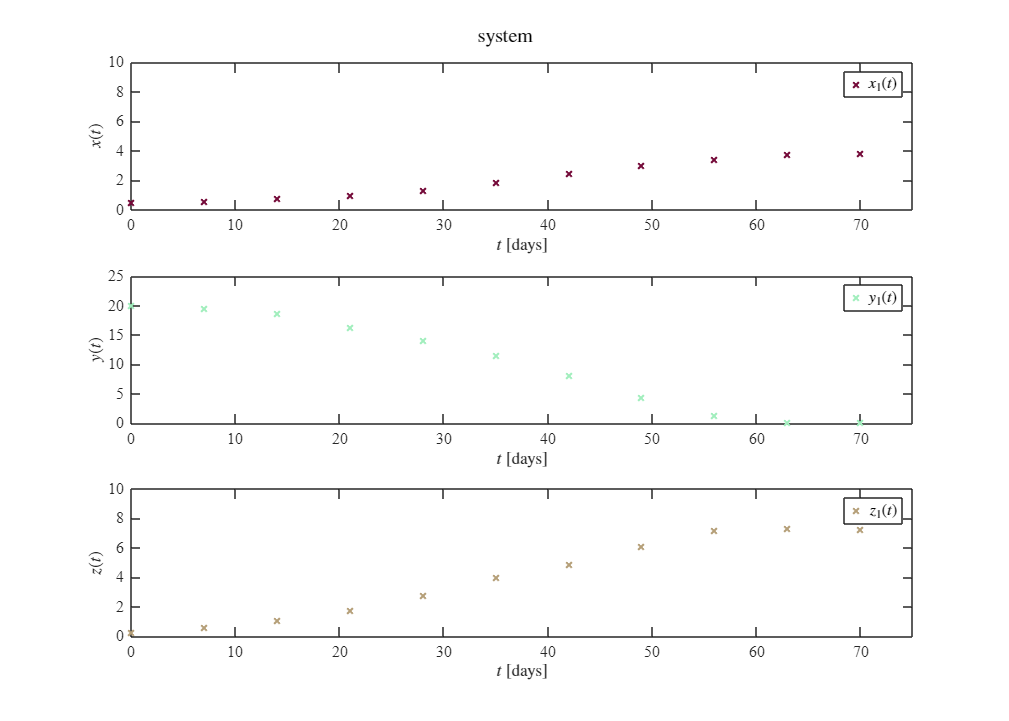

clc; clear; close all; warning('off','all')
filename = 'data2.csv';
sys = readmatrix(filename);
t = sys(:,1);
x1 = sys(:,2);
y1= sys(:,3);
z1 = sys(:,4);
T = array2table([t, x1, y1, z1], 'VariableNames', {'Time', 'x1(t)', 'y1(t)', 'z1(t)'});

disp(T); plotEDOsxd(t,x1,y1,z1); ttl = ' system'; sgtitle(ttl,'Interpreter','Latex')

## Smoothing

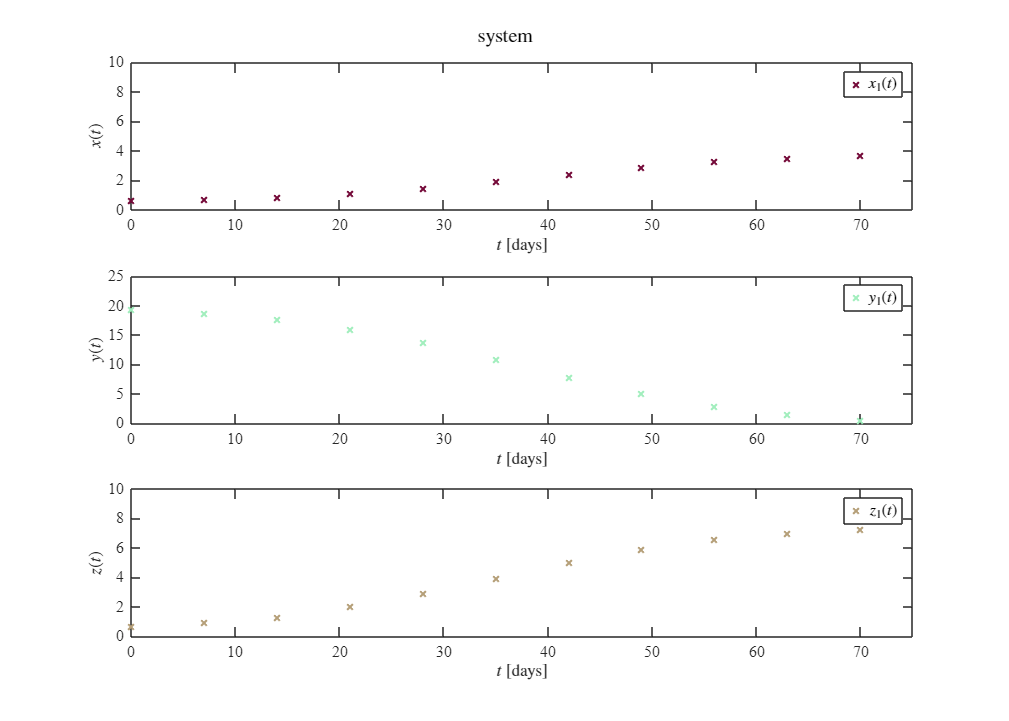

x1s = smoothdata(x1);
y1s = smoothdata(y1);
z1s = smoothdata(z1);

plotEDOs2(t,x1s,y1s,z1s); ttl = ' system'; sgtitle(ttl,'Interpreter','Latex')

T1 = array2table([t, x1s, y1s, z1s], 'VariableNames', {'Time', 'x1(t)', 'y1(t)', 'z1(t)'});
writetable(T1,'Smooth_data2.csv');



## Normalize data

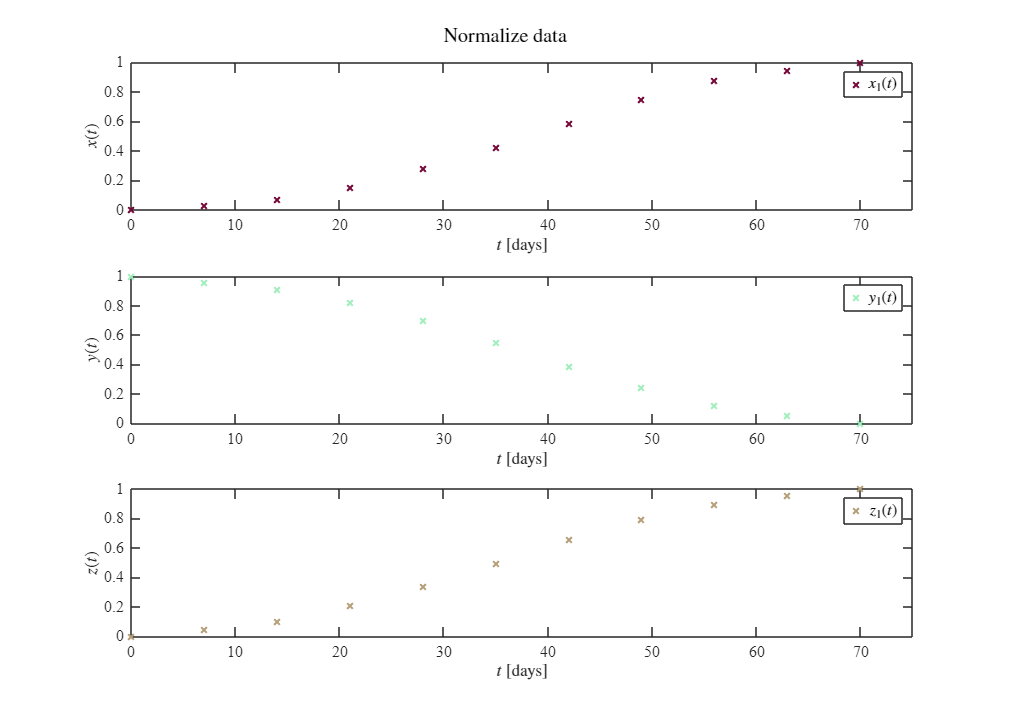

filename = 'Smooth_data2.csv';
sys = readmatrix(filename);
t = sys(:,1);
x = sys(:,2);
y = sys(:,3);
z = sys(:,4);

% Normalización min-max
x_norm = (x - min(x)) / (max(x) - min(x));
y_norm = (y - min(y)) / (max(y) - min(y));
z_norm = (z - min(z)) / (max(z) - min(z));

% Graficar con la nueva función
plotEDOsNorm(t, x_norm, y_norm, z_norm); ttl = ' Normalize data'; sgtitle(ttl,'Interpreter','Latex')

## Linear Regression

% Leer el archivo correctamente
filename = 'Smooth_data2.csv';
sys = readmatrix(filename);
t = sys(:,1);
x = sys(:,2);
y= sys(:,3);
z = sys(:,4);


P0x = [0.000761528747328915, 5.40193151929626e-5];     
P0y = [0.0139506931568651, 0.0288201962071527];              
P0z = [0.0741556526131045, 0.0192439855016189];
        
P0 = [P0x, P0y, P0z];  

mdl = ModelXYZ(t, x, y, z, P0x, P0y, P0z);


--- Ajuste del Modelo XYZ ---
Tamaño de muestra: 11
Parámetros ajustados: 6
Grados de libertad: 24
R^2 ajustado: 0.9954
AIC corregido: 84.3921

    Parameter     Estimate      StdError        MoE                  CI95                PValue  
    _________    __________    __________    __________    ________________________    __________

      "p1"       0.00077525    6.6718e-05     0.0001377    0.00063755    0.00091295    2.4268e-11
      "p2"       3.0776e-05    9.7428e-06    2.0108e-05    1.0667e-05    5.0884e-05     0.0042427
      "p3"         0.015219     0.0016395     0.0033838      0.011835      0.018602     2.062e-09
      "p4"         0.030408      0.002845     0.0058717      0.024536       0.03628    1.3188e-10
      "p5"         0.071353     0.0020469     0.0042246      0

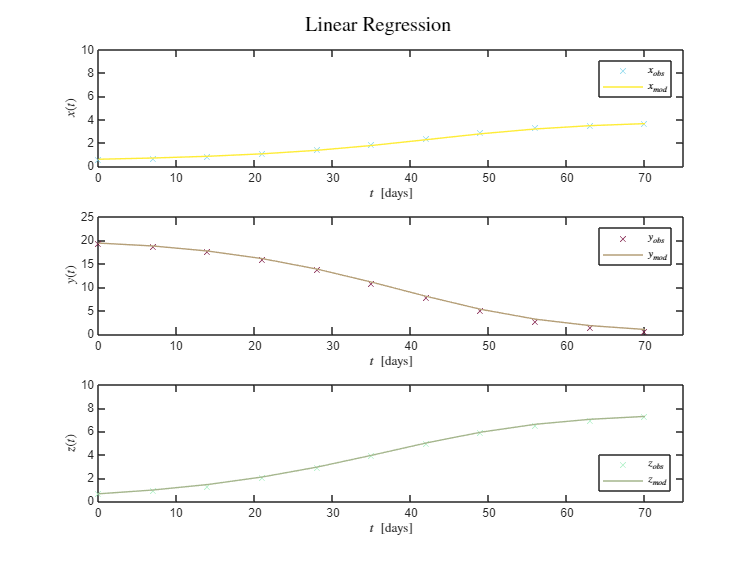

Pest = table2array(mdl.Coefficients(:,1));

[~, x_fit, y_fit, z_fit] = simulateXYZ(t, x(1), y(1), z(1), Pest);

plotXYZResults(t, [x, x_fit], [y, y_fit], [z, z_fit]); ttl = ' Linear Regression'; sgtitle(ttl,'Interpreter','Latex')

## Equilibrium points and jacobian matrix

clc; clear; close all; warning('off','all')

syms x y z
p = sym('p', [1 6]);  % Define un vector simbólico p(1) a p(7)

   dx = p(1)*x*y*z + p(2)*x*y^2;
   dy = p(3)*y - p(4)*x*y;
   dz = p(5)*z - p(6)*x*z;
J = jacobian([dx, dy, dz], [x, y, z]);
fprintf('Jacobian matrix of the system:\n');disp(J)

Jacobian matrix of the system:


$$\left(\begin{array}{ccc} p_{2}\,y^{2}+p_{1}\,z\,y & 2\,p_{2}\,x\,y+p_{1}\,x\,z & p_{1}\,x\,y\\ -p_{4}\,y & p_{3}-p_{4}\,x & 0\\ -p_{6}\,z & 0 & p_{5}-p_{6}\,x \end{array}\right)$$

eq1 = dx == 0;
eq2 = dy == 0;
eq3 = dz == 0;
edos = solve([eq1, eq2, eq3], [x, y, z]);

n = length(edos.x);
fprintf('Equilibrium Points of the system:\n');fprintf('The system has %d equilibrium point(s).\n\n', n);

Equilibrium Points of the system:
The system has 2 equilibrium point(s).



for i = 1:min(2,n)
    X = edos.x(i);
    Y = edos.y(i);
    Z = edos.z(i);
    syms x y z
    fprintf('Equilibrium point %d:\n', i);
    disp([x y z X Y Z])
end

Equilibrium point 1:


$$\left(\begin{array}{cccccc} x & y & z & \frac{p_{5}}{p_{6}} & 0 & 0 \end{array}\right)$$

Equilibrium point 2:


$$\left(\begin{array}{cccccc} x & y & z & 0 & 0 & 0 \end{array}\right)$$

## Local stability

clc; clear; close all; warning('off','all')

% Parámetros
p1 = 0.000761528747328915;
p2 = 5.40193151929626e-5;
p3 = 0.0139506931568651;
p4 = 0.0288201962071527;
p5 = 0.0741556526131045;
p6 = 0.0192439855016189;

x1 = 0; y1 = 0; z1 = 0;
x2 = p3 / p4;
y2 = 1;
z2 = -p2 / p1;

x = [x1; x2];
y = [y1; y2];
z = [z1; z2];
var = {'(x0,y0,z0)'; '(x1,y1,z1)'};

Equilibria = table(x, y, z, 'RowNames', var);
Equilibria.Properties.VariableNames = {'xe','ye','ze'};
fprintf('Equilibrium points of the  system:\n');disp(Equilibria)

Equilibrium points of the  system:
                    xe       ye       ze    
                  _______    __    _________

    (x0,y0,z0)          0    0             0
    (x1,y1,z1)    0.48406    1     -0.070935




syms xs ys zs
J = [ p2*ys^2 + p1*zs*ys,   2*p2*xs*ys + p1*xs*zs,   p1*xs*ys;
     -p4*ys,              p3 - p4*xs,               0;
     -p6*zs,              0,                       p5 - p6*xs ];


L = zeros(2,3);
for i = 1:2
    Ji = double(subs(J, {xs, ys, zs}, {x(i), y(i), z(i)}));
    L(i,:) = sort(eig(Ji), 'descend');
end

% Tabla de autovalores
L1 = L(:,1); L2 = L(:,2); L3 = L(:,3);
Lambdas = table(L1, L2, L3, 'RowNames', var);
disp('Eigenvalues of the Jacobian matrix evaluated at each equilibrium point:');disp(Lambdas)

Eigenvalues of the Jacobian matrix evaluated at each equilibrium point:
                     L1                 L2                         L3           
                  ________    _______________________    _______________________

    (x0,y0,z0)    0.074156       0.013951+0i                       0+0i         
    (x1,y1,z1)    0.064848    -3.8792e-06+0.00086804i    -3.8792e-06-0.00086804i



## 2T prediction

filename = 'Smooth_data2.csv';
sys = readmatrix(filename);
t = sys(:,1);
x = sys(:,2);
y= sys(:,3);
z = sys(:,4);
P0x = [0.000761528747328915, 5.40193151929626e-5];     
P0y = [0.0139506931568651, 0.0288201962071527];              
P0z = [0.0741556526131045, 0.0192439855016189];
P0 = [P0x, P0y, P0z];  % Vector total de parámetros
mdl = ModelXYZ(t, x, y, z, P0x, P0y, P0z);


--- Ajuste del Modelo XYZ ---
Tamaño de muestra: 11
Parámetros ajustados: 6
Grados de libertad: 24
R^2 ajustado: 0.9954
AIC corregido: 84.3921

    Parameter     Estimate      StdError        MoE                  CI95                PValue  
    _________    __________    __________    __________    ________________________    __________

      "p1"       0.00077525    6.6718e-05     0.0001377    0.00063755    0.00091295    2.4268e-11
      "p2"       3.0776e-05    9.7428e-06    2.0108e-05    1.0667e-05    5.0884e-05     0.0042427
      "p3"         0.015219     0.0016395     0.0033838      0.011835      0.018602     2.062e-09
      "p4"         0.030408      0.002845     0.0058717      0.024536       0.03628    1.3188e-10
      "p5"         0.071353     0.0020469     0.0042246      0

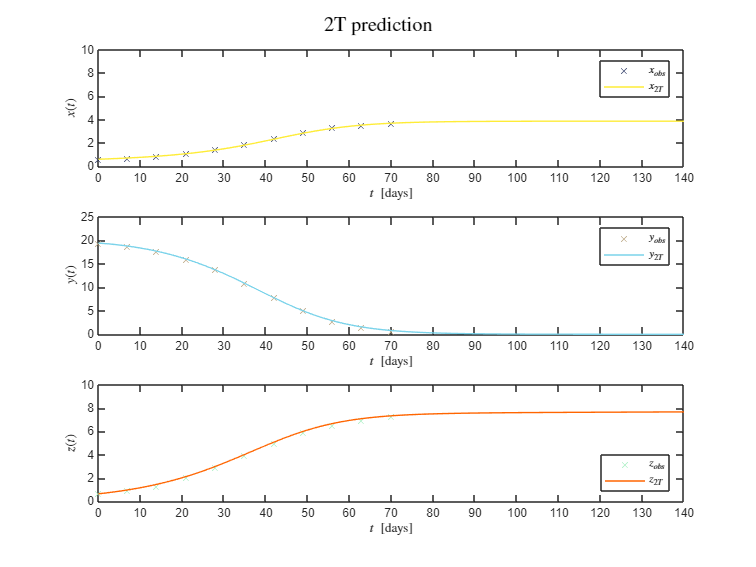


P = table2array(mdl.Coefficients(:,1));
dt = 1E-2;
tend = 1000;
[tp, xp, yp, zp] = Predict(x(1), y(1), z(1), dt, tend, P);
plotXYZPredict(t, x, y, z, tp, xp, yp, zp); ttl = ' 2T prediction'; sgtitle(ttl,'Interpreter','Latex')

## Conclusion

### English

The analyzed dynamic system models the interaction between tumor cells, healthy tissue, and immune effector cells using a set of nonlinear differential equations. Based on parameter estimation and stability analysis, the system exhibits no biologically stable equilibrium where all three populations coexist. Instead, equilibrium points either correspond to total cell absence or dominance of tumor cells in the absence of immune response and healthy tissue. This reflects an aggressive disease progression scenario, such as metastatic melanoma, where the tumor proliferates uncontrollably while suppressing the immune system and destroying surrounding tissue. Numerical simulations support this behavior, showing rapid tumor growth, immune stagnation, and tissue collapse. Overall, the system effectively captures a pathological, unstable biological environment and may serve as a foundation for exploring therapeutic strategies like immunotherapy in future studies.

### Español

El sistema dinámico analizado modela la interacción entre células tumorales, tejido sano y células efectoras del sistema inmunológico mediante un conjunto de ecuaciones diferenciales no lineales. A partir de la estimación de parámetros y el análisis de estabilidad, se concluye que el sistema no presenta un equilibrio biológico estable donde coexistan las tres poblaciones. En su lugar, los puntos de equilibrio corresponden a estados sin células o con dominio absoluto del tumor, en ausencia de tejido sano y respuesta inmune. Esto representa un escenario de progresión agresiva de la enfermedad, como en el caso del melanoma metastásico, donde el tumor crece sin control, suprime al sistema inmunológico y destruye el entorno tisular. Las simulaciones numéricas respaldan esta dinámica, mostrando un crecimiento acelerado del tumor, estancamiento inmunológico y colapso del tejido sano. En conjunto, el sistema describe eficazmente un entorno biológico inestable y patológico, y puede servir como base para explorar estrategias terapéuticas como la inmunoterapia en estudios futuros.

## MDL

function mdl = ModelXYZ(t, x, y, z, P0x, P0y, P0z)
    dt = 1E-1;
    fo = [diff(x)/dt; diff(y)/dt; diff(z)/dt];
    to = [t(2:end); t(2:end); t(2:end)];

    t_base = t; 

    function f_pred = model(p, ~)
        [~, x_, y_, z_] = simulateXYZ(t_base, x(1), y(1), z(1), p);
        dxdt_ = diff(x_) / dt;
        dydt_ = diff(y_) / dt;
        dzdt_ = diff(z_) / dt;
        f_pred = [dxdt_; dydt_; dzdt_];
    end

       P0 = [P0x, P0y, P0z];
    mdl = fitnlm(to, fo, @model, P0);

    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    Pvalue = table2array(mdl.Coefficients(:,4));
    CI95 = coefCI(mdl, 0.05);
    MoE = SE .* tinv(0.975, mdl.DFE);
    param_names = compose("p%d", 1:length(P0));
    Results = table(param_names', Estimate, SE, MoE, CI95, Pvalue, ...
        'VariableNames', {'Parameter', 'Estimate', 'StdError', 'MoE', 'CI95', 'PValue'});

    fprintf('\n--- Ajuste del Modelo XYZ ---\n')
    fprintf('Tamaño de muestra: %d\n', length(x))
    fprintf('Parámetros ajustados: %d\n', length(P0))
    fprintf('Grados de libertad: %d\n', mdl.DFE)
    fprintf('R^2 ajustado: %.4f\n', mdl.Rsquared.Adjusted)
    fprintf('AIC corregido: %.4f\n\n', mdl.ModelCriterion.AICc)
    disp(Results)
end


function [dx, dy, dz] = dynamics(x, y, z, p)


    dx = p(1)*x*y*z + p(2)*x*y^2;

   
    dy = p(3)*y - p(4)*x*y;

   dz = p(5)*z - p(6)*x*z;


end


function [t_, x_, y_, z_] = simulateXYZ(t, x0, y0, z0, p)
    dt = mean(diff(t));
    t_ = (0:dt:max(t))';
    n = length(t_) - 1;

    x_ = zeros(n+1,1); x_(1) = x0;
    y_ = zeros(n+1,1); y_(1) = y0;
    z_ = zeros(n+1,1); z_(1) = z0;

    for i = 1:n
        [dx1, dy1, dz1] = dynamics(x_(i), y_(i), z_(i), p);
        [dx2, dy2, dz2] = dynamics(x_(i)+dx1*dt, y_(i)+dy1*dt, z_(i)+dz1*dt, p);
        x_(i+1) = x_(i) + 0.5*(dx1 + dx2)*dt;
        y_(i+1) = y_(i) + 0.5*(dy1 + dy2)*dt;
        z_(i+1) = z_(i) + 0.5*(dz1 + dz2)*dt;
    end

    x_ = interp1(t_, x_, t);
    y_ = interp1(t_, y_, t);
    z_ = interp1(t_, z_, t);
end

## Functions

## Graphics

function plotEDOsxd(t, x1, y1, z1)
    c1 = [116, 9, 56] / 255;  
    c2 = [161, 238, 189] / 255;  
    c3 = [181, 159, 120] / 255; 

    figure('Color', 'w', 'Units', 'centimeters', 'Position', [2, 2, 28, 20]);

    % Subplot 1: x(t)
    subplot(3, 1, 1)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 12);
    hold on; box on; grid off;
    plot(t, x1, 'x', 'LineWidth', 1.5, 'Color', c1)
    xlabel('$t$ [days]', 'Interpreter', 'latex', 'FontSize', 13)
    ylabel('$x(t)$', 'Interpreter', 'latex', 'FontSize', 13)
    xlim([0 75]); xticks(0:10:75)
    ylim([0 10]); yticks(0:2:10)
    legend('$x_1(t)$', 'Interpreter', 'latex', 'FontSize', 12, 'Location', 'NorthEast')

    % Subplot 2: y(t)
    subplot(3, 1, 2)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 12);
    hold on; box on; grid off;
    plot(t, y1, 'x', 'LineWidth', 1.5, 'Color', c2)
    xlabel('$t$ [days]', 'Interpreter', 'latex', 'FontSize', 13)
    ylabel('$y(t)$', 'Interpreter', 'latex', 'FontSize', 13)
    xlim([0 75]); xticks(0:10:75)
    ylim([0 25]); yticks(0:5:25)
    legend('$y_1(t)$', 'Interpreter', 'latex', 'FontSize', 12, 'Location', 'NorthEast')

    % Subplot 3: z(t)
    subplot(3, 1, 3)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 12);
    hold on; box on; grid off;
    plot(t, z1, 'x', 'LineWidth', 1.5, 'Color', c3)
    xlabel('$t$ [days]', 'Interpreter', 'latex', 'FontSize', 13)
    ylabel('$z(t)$', 'Interpreter', 'latex', 'FontSize', 13)
    xlim([0 75]); xticks(0:10:75)
    ylim([0 10]); yticks(0:2:10)
    legend('$z_1(t)$', 'Interpreter', 'latex', 'FontSize', 12, 'Location', 'NorthEast')
end


function plotEDOs2(t, x1s, y1s, z1s)
    c1 = [116, 9, 56] / 255;  
    c2 = [161, 238, 189] / 255;  
    c3 = [181, 159, 120] / 255; 

    figure('Color', 'w', 'Units', 'centimeters', 'Position', [2, 2, 28, 20]);

    % Subplot 1: x(t)
    subplot(3, 1, 1)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 12);
    hold on; box on; grid off;
    plot(t, x1s, 'x', 'LineWidth', 1.5, 'Color', c1)
    xlabel('$t$ [days]', 'Interpreter', 'latex', 'FontSize', 13)
    ylabel('$x(t)$', 'Interpreter', 'latex', 'FontSize', 13)
    xlim([0 75]); xticks(0:10:75)
    ylim([0 10]); yticks(0:2:10)
    legend('$x_1(t)$', 'Interpreter', 'latex', 'FontSize', 12, 'Location', 'NorthEast')

    % Subplot 2: y(t)
    subplot(3, 1, 2)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 12);
    hold on; box on; grid off;
    plot(t, y1s, 'x', 'LineWidth', 1.5, 'Color', c2)
    xlabel('$t$ [days]', 'Interpreter', 'latex', 'FontSize', 13)
    ylabel('$y(t)$', 'Interpreter', 'latex', 'FontSize', 13)
    xlim([0 75]); xticks(0:10:75)
    ylim([0 25]); yticks(0:5:25)
    legend('$y_1(t)$', 'Interpreter', 'latex', 'FontSize', 12, 'Location', 'NorthEast')

    % Subplot 3: z(t)
    subplot(3, 1, 3)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 12);
    hold on; box on; grid off;
    plot(t, z1s, 'x', 'LineWidth', 1.5, 'Color', c3)
    xlabel('$t$ [days]', 'Interpreter', 'latex', 'FontSize', 13)
    ylabel('$z(t)$', 'Interpreter', 'latex', 'FontSize', 13)
    xlim([0 75]); xticks(0:10:75)
    ylim([0 10]); yticks(0:2:10)
    legend('$z_1(t)$', 'Interpreter', 'latex', 'FontSize', 12, 'Location', 'NorthEast')
end

function plotXYZPredict(to, xo, yo, zo, tp, xp, yp, zp)
    % Definición fija de colores similar al segundo código
    colores = [116, 9, 56;
               161, 238, 189;
               170, 84, 134;
               255, 101, 0;
               123, 211, 234;
               181, 159, 120;
               42,  54,  99;
               26,  26,  29;
               254, 236, 55;
               165, 182, 141] / 255;

    % Selección fija de colores para obs y mod (6 colores al azar sin repetir)
    rng('shuffle');
    indices = randperm(size(colores,1),6);
    c1_obs = colores(indices(1), :);
    c1_mod = colores(indices(2), :);
    c2_obs = colores(indices(3), :);
    c2_mod = colores(indices(4), :);
    c3_obs = colores(indices(5), :);
    c3_mod = colores(indices(6), :);

    figure(); set(gcf,'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,15])
    set(gca,'FontName','Times New Roman')
    fontsize(12,'points')

    % Subplot X
    subplot(3,1,1); hold on; box on;
    plot(to, xo, 'x', 'Color', c1_obs)
    plot(tp, xp, '-', 'Color', c1_mod)
    ylabel('$x(t)$','Interpreter','latex')
    xlabel('$t\ \mathrm{[days]}$', 'Interpreter','latex')  % ← Corregido
    legend({'$x_{obs}$','$x_{2T}$'}, 'Interpreter','latex', 'Location', 'Best')
    xticks(0:10:140); xlim([0 140]);
    ylim([0 10]); yticks(0:2:10)

    % Subplot Y
    subplot(3,1,2); hold on; box on;
    plot(to, yo, 'x', 'Color', c2_obs)
    plot(tp, yp, '-', 'Color', c2_mod)
    ylabel('$y(t)$','Interpreter','latex')
    xlabel('$t\ \mathrm{[days]}$', 'Interpreter','latex')  % ← Corregido
    legend({'$y_{obs}$','$y_{2T}$'}, 'Interpreter','latex', 'Location', 'Best')
    xticks(0:10:140); xlim([0 140]);
    ylim([0 25]); yticks(0:5:25)

    % Subplot Z
    subplot(3,1,3); hold on; box on;
    plot(to, zo, 'x', 'Color', c3_obs)
    plot(tp, zp, '-', 'Color', c3_mod)
    xlabel('$t\ \mathrm{[days]}$', 'Interpreter','latex')  % ← Corregido
    ylabel('$z(t)$','Interpreter','latex')
    legend({'$z_{obs}$','$z_{2T}$'}, 'Interpreter','latex', 'Location', 'Best')
    xticks(0:10:140); xlim([0 140]);
    ylim([0 10]); yticks(0:2:10)
end





function plotXYZPredict2(to, xo, yo, zo, tp, xp, yp, zp)
    % Definición fija de colores similar al segundo código
    colores = [116, 9, 56;
               161, 238, 189;
               170, 84, 134;
               255, 101, 0;
               123, 211, 234;
               181, 159, 120;
               42,  54,  99;
               26,  26,  29;
               254, 236, 55;
               165, 182, 141] / 255;

    % Selección fija de colores para obs y mod (6 colores al azar sin repetir)
    rng('shuffle');
    indices = randperm(size(colores,1),6);
    c1_obs = colores(indices(1), :);
    c1_mod = colores(indices(2), :);
    c2_obs = colores(indices(3), :);
    c2_mod = colores(indices(4), :);
    c3_obs = colores(indices(5), :);
    c3_mod = colores(indices(6), :);

    figure(); set(gcf,'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,15])
    set(gca,'FontName','Times New Roman')
    fontsize(12,'points')

    % Subplot X
    subplot(3,1,1); hold on; box on;
    plot(to, xo, 'x', 'Color', c1_obs)
    plot(tp, xp, '-', 'Color', c1_mod)
    ylabel('$x(t)$','Interpreter','latex')
    legend({'$x_{obs}$','$x_{2T}$'}, 'Interpreter','latex', 'Location', 'Best')
   xticks(0:100:1000); xlim([0 1000]);
    ylim([0 10]); yticks(0:2:10)

    % Subplot Y
    subplot(3,1,2); hold on; box on;
    plot(to, yo, 'x', 'Color', c2_obs)
    plot(tp, yp, '-', 'Color', c2_mod)
    ylabel('$y(t)$','Interpreter','latex')
    legend({'$y_{obs}$','$y_{2T}$'}, 'Interpreter','latex', 'Location', 'Best')
    xticks(0:100:1000); xlim([0 1000]);
    ylim([0 25]); yticks(0:5:25)

    % Subplot Z
    subplot(3,1,3); hold on; box on;
    plot(to, zo, 'x', 'Color', c3_obs)
    plot(tp, zp, '-', 'Color', c3_mod)
    xlabel('$t\ \text{[días]}$','Interpreter','latex')
    ylabel('$z(t)$','Interpreter','latex')
    legend({'$z_{obs}$','$z_{2T}$'}, 'Interpreter','latex', 'Location', 'Best')
    xticks(0:100:1000); xlim([0 1000]);
    ylim([0 10]); yticks(0:2:10)
end







## Plot mdl

function plotXYZResults(t, X, Y, Z)
    
    colores = [116, 9, 56;
               161, 238, 189;
               170, 84, 134;
               255, 101, 0;
               123, 211, 234;
               181, 159, 120;
               42,  54,  99;
               26,  26,  29;
               254, 236, 55;
               165, 182, 141] / 255;

    
    rng('shuffle');
    indices = randperm(size(colores,1), 6);
    c1_obs = colores(indices(1), :);
    c1_mod = colores(indices(2), :);
    c2_obs = colores(indices(3), :);
    c2_mod = colores(indices(4), :);
    c3_obs = colores(indices(5), :);
    c3_mod = colores(indices(6), :);

    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,15])
    set(gca,'FontName','Times New Roman')
    fontsize(12,'points')

    % Subplot X
    subplot(3,1,1)
    hold on; box on;
    plot(t, X(:,1), 'x', 'Color', c1_obs)
    plot(t, X(:,2), '-', 'Color', c1_mod)
    ylabel('$x(t)$','Interpreter','latex')
    xlabel('$t\ \mathrm{[days]}$', 'Interpreter','latex')  % ← Corregido
    legend({'$x_{obs}$','$x_{mod}$'}, 'Interpreter','latex', 'Location', 'Best')
    xlim([0 75]); xticks(0:10:75)
    ylim([0 10]); yticks(0:2:10)

    % Subplot Y
    subplot(3,1,2)
    hold on; box on;
    plot(t, Y(:,1), 'x', 'Color', c2_obs)
    plot(t, Y(:,2), '-', 'Color', c2_mod)
    ylabel('$y(t)$','Interpreter','latex')
    xlabel('$t\ \mathrm{[days]}$', 'Interpreter','latex')  % ← Corregido
    legend({'$y_{obs}$','$y_{mod}$'}, 'Interpreter','latex', 'Location', 'Best')
    xlim([0 75]); xticks(0:10:75)
    ylim([0 25]); yticks(0:5:25)

    % Subplot Z
    subplot(3,1,3)
    hold on; box on;
    plot(t, Z(:,1), 'x', 'Color', c3_obs)
    plot(t, Z(:,2), '-', 'Color', c3_mod)
    xlabel('$t\ \mathrm{[days]}$', 'Interpreter','latex')  % ← Corregido
    ylabel('$z(t)$','Interpreter','latex')
    legend({'$z_{obs}$','$z_{mod}$'}, 'Interpreter','latex', 'Location', 'Best')
    xlim([0 75]); xticks(0:10:75)
    ylim([0 10]); yticks(0:2:10)
end




## Plot Normalized data

function plotEDOsNorm(t, x1, y1, z1)
    c1 = [116, 9, 56] / 255;       % Color para x(t)
    c2 = [161, 238, 189] / 255;    % Color para y(t)
    c3 = [181, 159, 120] / 255;    % Color para z(t)

    figure('Color', 'w', 'Units', 'centimeters', 'Position', [2, 2, 28, 20]);

   
    subplot(3, 1, 1)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 12);
    hold on; box on; grid off;
    plot(t, x1, 'x', 'LineWidth', 1.5, 'Color', c1)
    xlabel('$t$ [days]', 'Interpreter', 'latex', 'FontSize', 13)
    ylabel('$x(t)$', 'Interpreter', 'latex', 'FontSize', 13)
    xlim([0 75]); xticks(0:10:75)
    ylim([0 1]); yticks(0:0.2:1)
    legend('$x_1(t)$', 'Interpreter', 'latex', 'FontSize', 12, 'Location', 'NorthEast')

    
    subplot(3, 1, 2)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 12);
    hold on; box on; grid off;
    plot(t, y1, 'x', 'LineWidth', 1.5, 'Color', c2)
    xlabel('$t$ [days]', 'Interpreter', 'latex', 'FontSize', 13)
    ylabel('$y(t)$', 'Interpreter', 'latex', 'FontSize', 13)
    xlim([0 75]); xticks(0:10:75)
    ylim([0 1]); yticks(0:0.2:1)
    legend('$y_1(t)$', 'Interpreter', 'latex', 'FontSize', 12, 'Location', 'NorthEast')

   
    subplot(3, 1, 3)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 12);
    hold on; box on; grid off;
    plot(t, z1, 'x', 'LineWidth', 1.5, 'Color', c3)
    xlabel('$t$ [days]', 'Interpreter', 'latex', 'FontSize', 13)
    ylabel('$z(t)$', 'Interpreter', 'latex', 'FontSize', 13)
    xlim([0 75]); xticks(0:10:75)
    ylim([0 1]); yticks(0:0.2:1)
    legend('$z_1(t)$', 'Interpreter', 'latex', 'FontSize', 12, 'Location', 'NorthEast')
end


## 2t Predict

function [t, x, y, z] = Predict(x0, y0, z0, dt, tend, P)
    
    rho1 = P(1);
    rho2 = P(2);
    rho3 = P(3);
    rho4 = P(4);
    rho5 = P(5);
    rho6 = P(6);
    %rho7 = P(7);

    
    t = (0:dt:tend)';
    N = length(t);
    x = zeros(N, 1); x(1) = x0;
    y = zeros(N, 1); y(1) = y0;
    z = zeros(N, 1); z(1) = z0;

    
    for i = 1:N-1
        [fx, fy, fz] = f(x(i), y(i), z(i));
        xn = x(i) + fx * dt;
        yn = y(i) + fy * dt;
        zn = z(i) + fz * dt;
        [fxn, fyn, fzn] = f(xn, yn, zn);

        x(i+1) = x(i) + (fx + fxn) * dt / 2;
        y(i+1) = y(i) + (fy + fyn) * dt / 2;
        z(i+1) = z(i) + (fz + fzn) * dt / 2;
    end

    
    function [dx, dy, dz] = f(x, y, z)
         dx = rho1 * x * y * z + rho2 * x * y^2;
         dy = rho3 * y - rho4 * x * y;
         dz = rho5 * z - rho6 * x * z;
    end
end
